org = Org;
org.init;

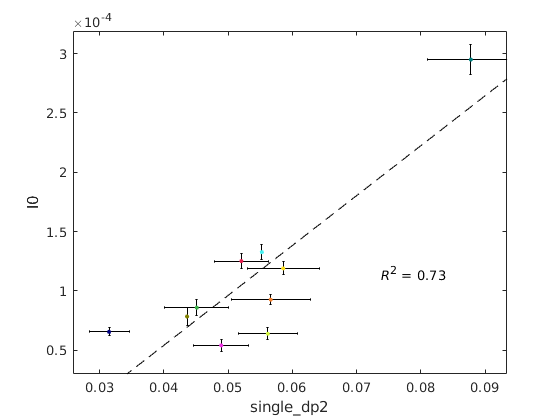

Using only 73 out of 110 sessions
Mouse-aggregated correlations single_dp2 vs. I0: adj. R^2 = 0.730
Pearson: 0.872, p = 1.011597e-03, **
Spearman: 0.564, p = 9.579157e-02, n.s
Kendall: 0.467, p = 7.255015e-02, n.s


figure;
org.correlogram('single_dp2', 'I0', true, true);

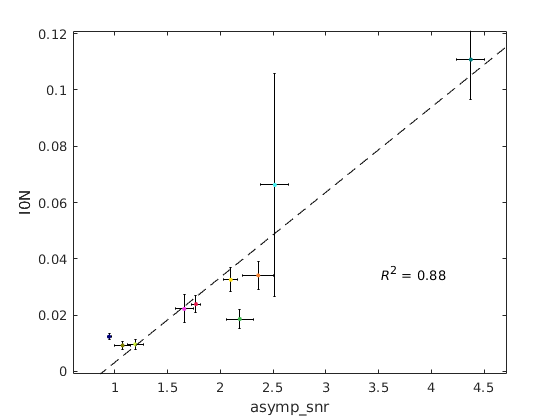

Using only 73 out of 110 sessions
Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.876
Pearson: 0.943, p = 4.193936e-05, ***
Spearman: 0.891, p = 1.380267e-03, **
Kendall: 0.778, p = 9.463183e-04, ***


figure;
org.correlogram('asymp_snr', 'I0N', true, true);

var1 = 'single_dp2';
var2 = 'I0';

a = org.sess_prop.(var1);
ac = org.sess_prop_conf.(var1);

d = org.sess_prop.(var2);
dc = org.sess_prop_conf.(var2);

my_mice = org.mouse;
filt = SessManager.highqual_filt_from_usable;
filt = filt & ~strcmp(my_mice, 'Mouse2019');

a=a(filt);ac=ac(filt);d=d(filt);dc=dc(filt);my_mice=my_mice(filt);
[am, amc] = Org.agg(my_mice, a, ac);
[dm, dmc] = Org.agg(my_mice, d, dc);
[p,pp,s,sp,k,kp,adjr2]=Org.corr_check(am,dm);
fprintf('Mouse-aggregated correlations %s vs. %s: adj. R^2 = %.3f\n', var1, var2, adjr2);

Mouse-aggregated correlations single_dp2 vs. I0: adj. R^2 = 0.141


fprintf('Pearson: %.3f, p = %e, %s\n', p, pp, Utils.pstar(pp));

Pearson: 0.498, p = 1.721961e-01, n.s


fprintf('Spearman: %.3f, p = %e, %s\n', s, sp, Utils.pstar(sp));

Spearman: 0.400, p = 2.911927e-01, n.s


fprintf('Kendall: %.3f, p = %e, %s\n', k, kp, Utils.pstar(kp));

Kendall: 0.333, p = 2.595183e-01, n.s


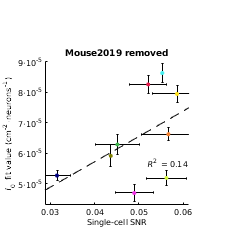


figure;
PanelGenerator.plot_regress_averaged(a,d,ac,dc,my_mice,'k', 'dotsize', 10);
%xlabel(esc(var1)); ylabel(var2);
Utils.fix_exponent(gca, 'y', 0);
xlabel 'Single-cell SNR'
ylabel '{\itI}_0 fit value (cm^{-2}\cdotneurons^{-1})'
title 'Mouse2019 removed'
figure_format([1.5 1.5])
Utils.printto('events_figs/f3_supplements', 'single_cell_snr_outlier_removed');

var1 = 'asymp_snr';
var2 = 'I0N';

a = org.sess_prop.(var1);
ac = org.sess_prop_conf.(var1);

d = org.sess_prop.(var2);
dc = org.sess_prop_conf.(var2);

my_mice = org.mouse;
filt = SessManager.highqual_filt_from_usable;
filt = filt & ~strcmp(my_mice, 'Mouse2019');

a=a(filt);ac=ac(filt);d=d(filt);dc=dc(filt);my_mice=my_mice(filt);
[am, amc] = Org.agg(my_mice, a, ac);
[dm, dmc] = Org.agg(my_mice, d, dc);
[p,pp,s,sp,k,kp,adjr2]=Org.corr_check(am,dm);
fprintf('Mouse-aggregated correlations %s vs. %s: adj. R^2 = %.3f\n', var1, var2, adjr2);

Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.601


fprintf('Pearson: %.3f, p = %e, %s\n', p, pp, Utils.pstar(pp));

Pearson: 0.807, p = 8.604095e-03, **


fprintf('Spearman: %.3f, p = %e, %s\n', s, sp, Utils.pstar(sp));

Spearman: 0.850, p = 6.073633e-03, **


fprintf('Kendall: %.3f, p = %e, %s\n', k, kp, Utils.pstar(kp));

Kendall: 0.722, p = 5.886243e-03, **


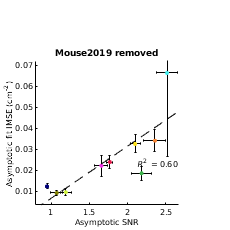


figure;
PanelGenerator.plot_regress_averaged(a,d,ac,dc,my_mice,'k', 'dotsize', 10);
%xlabel(esc(var1)); ylabel(var2);
xlabel 'Asymptotic SNR'
ylabel 'Asymptotic fit IMSE (cm^{-2})'
title 'Mouse2019 removed'
figure_format([1.5 1.5])
Utils.printto('events_figs/f3_supplements', 'asymp_snr_outlier_removed');